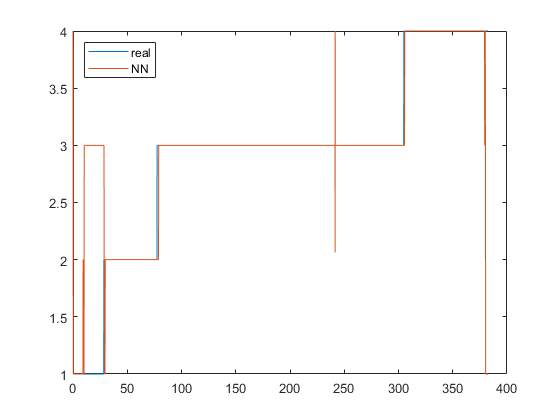

load load_to_test
old_w = str2double(to_try.power)';
old_t = str2double(to_try.time)'/2;
t = 0:1e-3:old_t(end);
w = fixpt_interp1(old_t,old_w,t,float('single'),[],float('single'),[],'Floor');

mm = str2double(to_try.legend_number)'+1;
mm = fixpt_interp1(old_t,mm,t,float('single'),[],float('single'),[],'Floor');
ll = out.pw_ph.data;
nnll = fixpt_interp1(t(end)/length(ll):t(end)/length(ll):t(end),ll,t,float('single'),[],float('single'),[],'Floor');


clf
figure(1)
plot(t,mm)
hold on
plot(t,nnll)
legend("real","NN","location","northwest")

% 
res = mm-nnll;
idx = res == 0;
tot = sum(idx(:));
acc = tot/length(mm)*100

acc = 93.6235